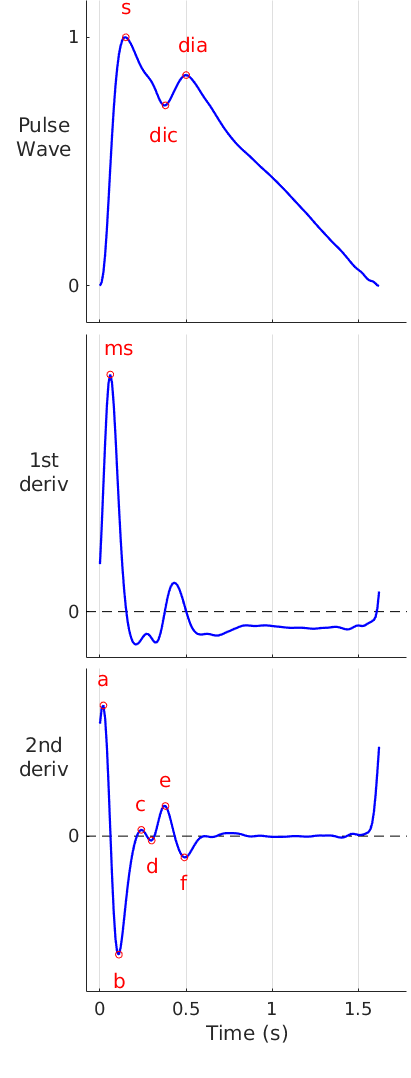

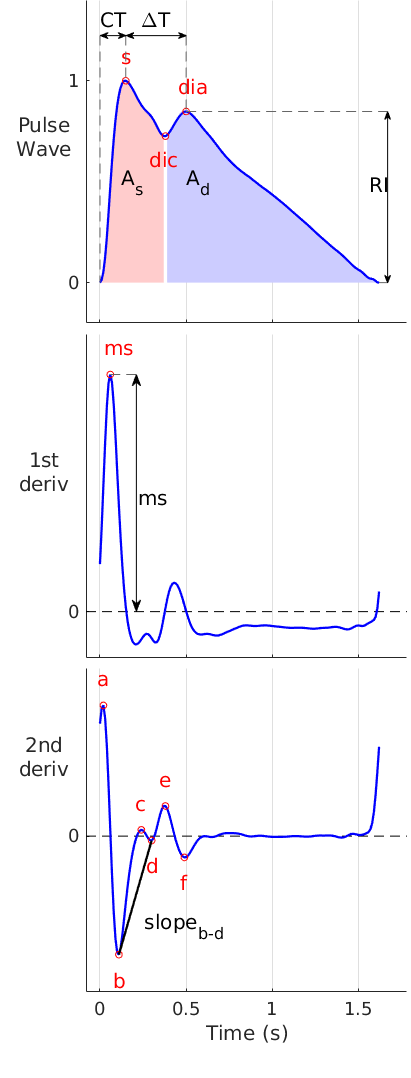

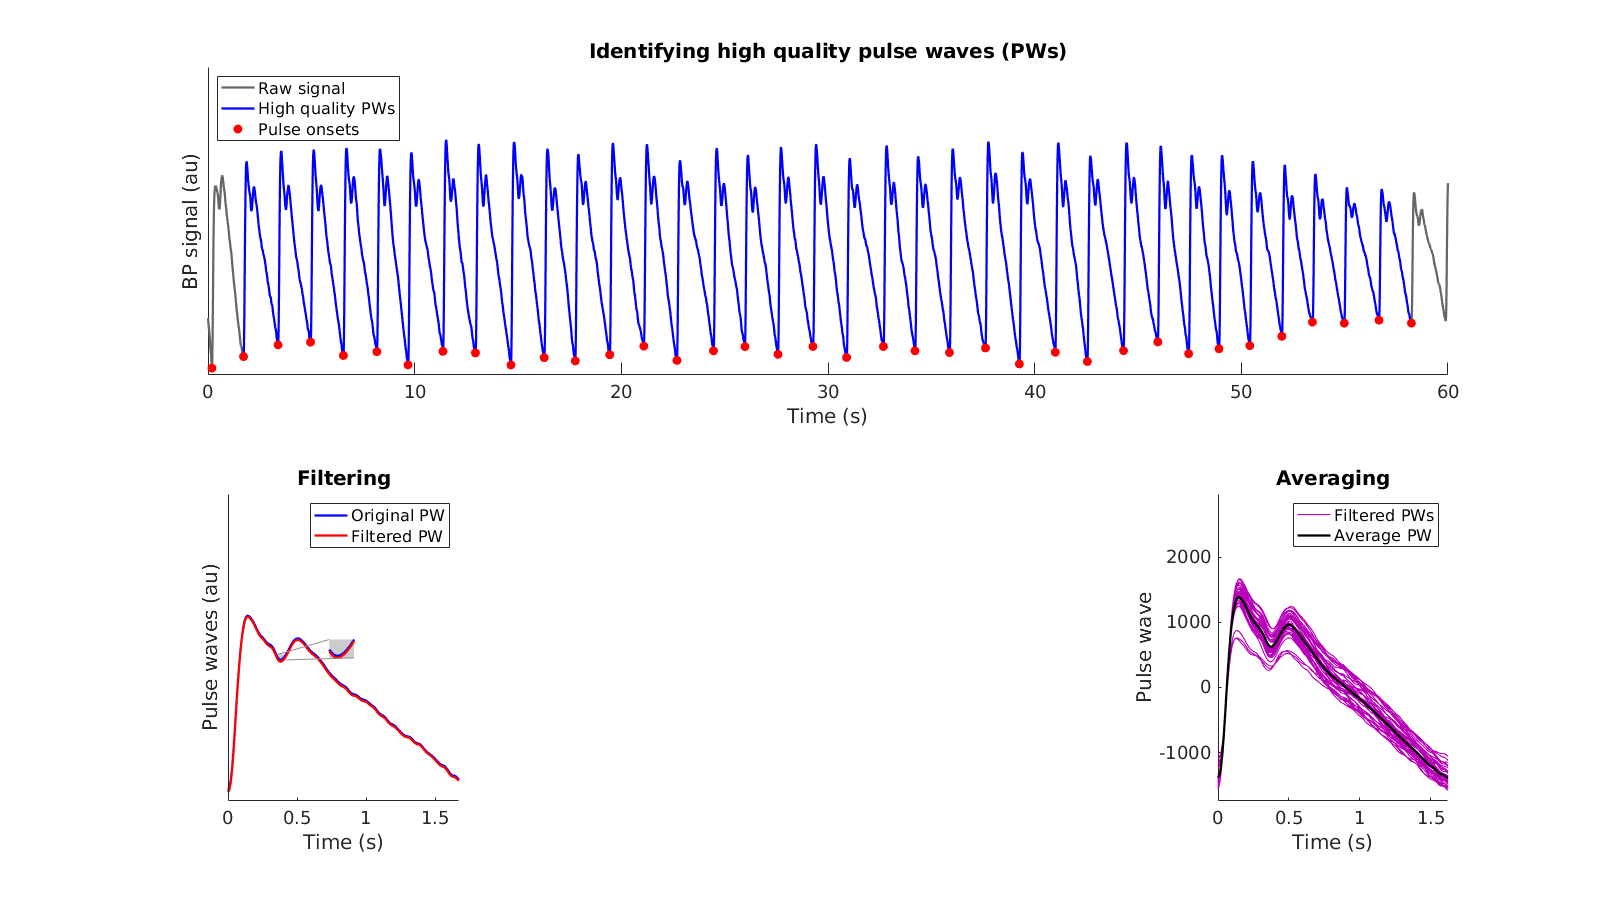

options.downsample =0;
options.calc_average_pw=1;
options.plot_areas =1;
load('PPGdiary1_1_min_sample.mat') % data is obtained from https://peterhcharlton.github.io/ppg-diary/datasets.html
[pw_inds, fid_pts, pulses, sigs] = PulseAnalyse(S,options);

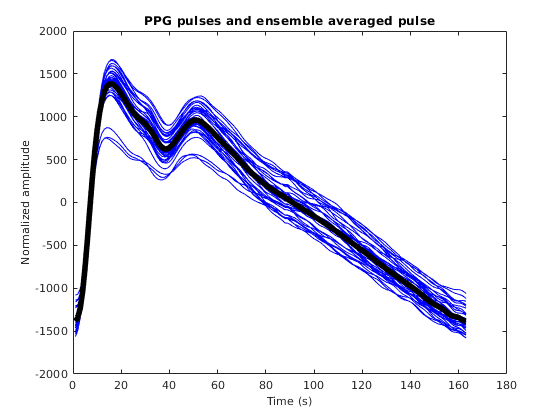


figure, plot(sigs.pws, 'b')
hold on, plot(sigs.ave, 'k', 'lineWidth', 5)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Normalized amplitude', 'FontSize', 10)
title('PPG pulses and ensemble averaged pulse')

Data is obtained form the finger using the reflective mode PPG. SpO2 is about 96%. It is useful to vidualize the data. The fiirst column is the signal from the red PPG and and second column is the signal obtained from the IR PPG. The sampling rate is 250 samples per second.    

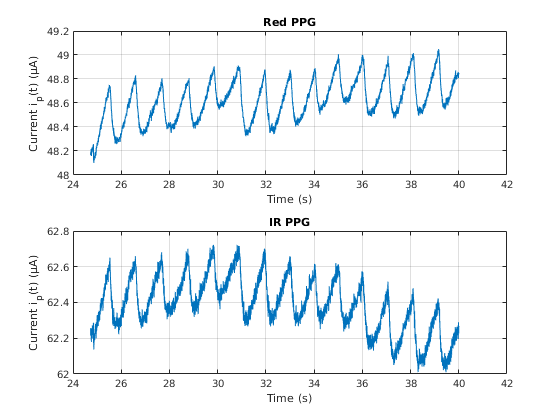

load('PPG_Data1.mat')

fs=250;
t=1/fs:1/fs:length(PPG_Data1)/fs;
start1 =6182;
figure, 
subplot(211) 
plot(t(start1:end),PPG_Data1(start1:end,1))
xlabel('Time (s)', 'FontSize', 10)
title('Red PPG')
ylabel('Current i_p(t) (µA)', 'FontSize', 10)
grid on
subplot(212) , plot(t(start1:end),PPG_Data1(start1:end,2))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Current i_p(t) (µA)', 'FontSize', 10)
title('IR PPG')
grid on

% need to be comleted
options.downsample =0;
options.calc_average_pw=1;
S.fs=250;
RED_AC=-highpass(PPG_Data1(:,1),0.5,fs);
RED_DC=lowpass(PPG_Data1(:,1),5,fs);
S.v=RED_AC;
[pulses_red, sigs_red] = PulseAnalyse(S,options);

Error using nan
NaN and Inf not allowed.

Error in PulseAnalyse>calculate_average_pw (line 1676)
        pws = nan(length(pulses.quality)-1, durn);

Error in PulseAnalyse (


S.fs=250;
S.v=-highpass(PPG_Data1(:,2),0.5,fs);
[pulses_IR, sigs_IR] = PulseAnalyse(S,options);